# Gaussian Mixture Example

mu = [1; 3; 5];
sigma = zeros(1,1,3);
sigma(1,1,1) = 1;
sigma(1,1,2) = 2;
sigma(1,1,3) = 0.5;

x = linspace(-2,7,200)';
N1 = normpdf(x,mu(1),sigma(1))

N1 =     0.0044
    0.0051
    0.0058
    0.0066
    0.0075
    0.0085
    0.0096
    0.0109
    0.0123
    0.0138


N2 = normpdf(x,mu(2),sigma(2))

N2 =     0.0088
    0.0093
    0.0098
    0.0104
    0.0109
    0.0116
    0.0122
    0.0129
    0.0136
    0.0143


N3 = normpdf(x,mu(3),sigma(3))

N3 =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


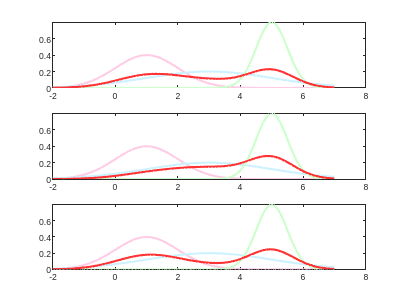


p1 = [0.33,0.33,0.34];
p2 = [0.1,0.5,0.4];
p3 = [0.4,0.2,0.4];

M1 = gmdistribution(mu,sigma,p1);
MM1 = M1.pdf(x);
M2 = gmdistribution(mu,sigma,p2);
MM2 = M2.pdf(x);
M3 = gmdistribution(mu,sigma,p3);
MM3 = M3.pdf(x);

figure(1)
subplot(3,1,1)
plot(x,N1,'LineWidth',2,'Color',[1 0.8 0.9 0.3])
hold on
plot(x,N2,'LineWidth',2,'Color',[0.8 0.95 1 0.3])
plot(x,N3,'LineWidth',2,'Color',[0.8 1 0.8 0.3])
plot(x,MM1,'LineWidth',2,'Color',[1 0.2 0.2 1])
hold off
subplot(3,1,2)
plot(x,N1,'LineWidth',2,'Color',[1 0.8 0.9 0.3])
hold on
plot(x,N2,'LineWidth',2,'Color',[0.8 0.95 1 0.3])
plot(x,N3,'LineWidth',2,'Color',[0.8 1 0.8 0.3])
plot(x,MM2,'LineWidth',2,'Color',[1 0.2 0.2 1])
hold off
subplot(3,1,3)
plot(x,N1,'LineWidth',2,'Color',[1 0.8 0.9 0.3])
hold on
plot(x,N2,'LineWidth',2,'Color',[0.8 0.95 1 0.3])
plot(x,N3,'LineWidth',2,'Color',[0.8 1 0.8 0.3])
plot(x,MM3,'LineWidth',2,'Color',[1 0.2 0.2 1])
hold off